# AI621 A4 : HDR Imaging & Tonemapping

20215584 Wonjoon Chang

Youtube: [https://youtu.be/TnPvvUt_sHQ](https://youtu.be/TnPvvUt_sHQ)

## Tonemapping

To display HDR images, we need to rescale values in a HDR image.

hdr = hdrread('./result/rendered_uniform_log.hdr');
% hdr = hdrread('./result/rendered_gaussian_log.hdr');

## Photographic Tonemapping

It applies the non-linear scaling to bring all pixels within [0,1] with leaving dark areas alone.

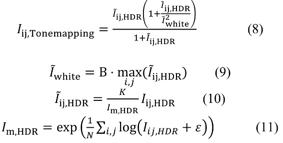

### RGB space

tm_img = tonemapping_rgb(hdr, 0.15, 0.95);
imwrite(im2uint8(tm_img), "./result/tm_uniform_15_95.jpg");

### XYZ space

tm_img = tonemapping_lumi(hdr, 0.15, 0.95);
imwrite(im2uint8(tm_img), "./result/tmL_uniform_15_95.jpg");

- K: 0.60, B : 0.95

- Now we can see all objects in the scene, but somewhat blurry.

- With smaller K, it was hard to identify the objects in the right parts. B did not significantly change the results.

## 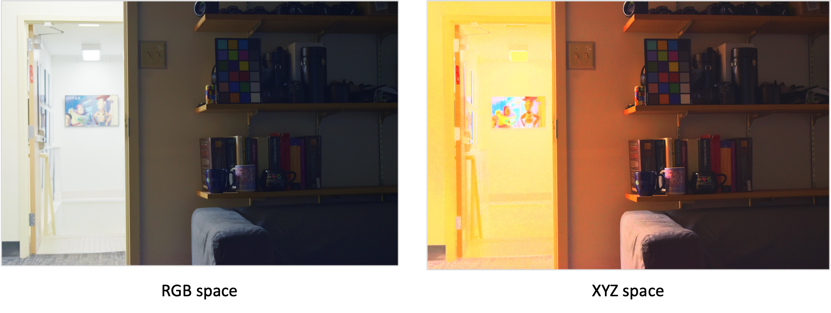

## Tonemapping with Bilateral Filtering

It preserves the detail and reduce the large scale contrast.

Bilateral Filtering extracts the base layer (blurred image) so that we can gain the details (edges) in the image by subtracting it.

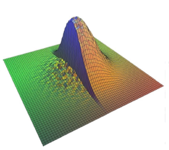

### RGB space

L = log(hdr);
minL = min(L,[],"all");
maxL = max(L,[],"all");
L_normed = double((L-minL)/(maxL-minL));

B = imbilatfilt(L_normed,0.4,20);

B2 = B*(maxL-minL)+minL;
D = L - B2;
S = 0.2;
for c=1:3
    maxB = max(B2(:,:,c),[],"all");
    tm_bi(:,:,c) = exp(S*(B2(:,:,c)-maxB)+D(:,:,c));
end

imwrite(im2uint8(tm_bi), "./result/tm_bi_uniform_02.jpg");

### XYZ space

XYZ = rgb2xyz(hdr);
X = XYZ(:,:,1);
Y = XYZ(:,:,2);
Z = XYZ(:,:,3);
x = X./(X+Y+Z);
y = Y./(X+Y+Z);

L = log(Y);
minL = min(L,[],"all");
maxL = max(L,[],"all");
L_normed = double((L-minL)/(maxL-minL));
B = imbilatfilt(L_normed,0.4,20);

B2 = B*(maxL-minL)+minL;
D = L - B2;
S = 0.2;
maxB = max(B2,[],"all");
Y = exp(S*(B2-maxB)+D);

[X,Y,Z] = xyY_to_XYZ(x,y,Y);
tm_bi = xyz2rgb(cat(3,X,Y,Z));

imwrite(im2uint8(tm_bi), "./result/tmL_bi_uniform_02.jpg");

- The compression factor 𝑆: 0.2

- Compared to the previous results, the details (edges) were preserved better.

- With larger S, the entire scene became very dark and the only visible part was the light on the left part.

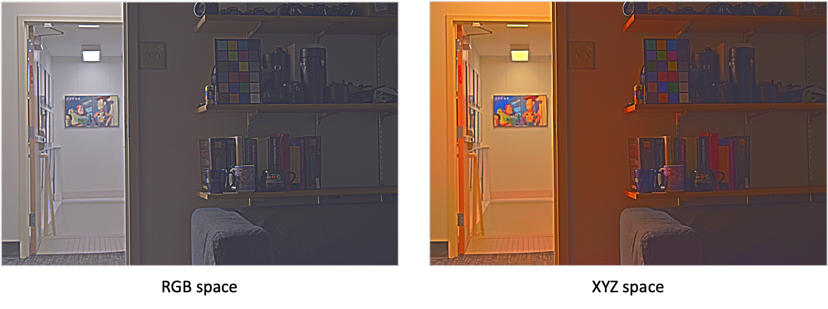

## My Own Images

Additionally, I performed the whole process on my own images.

- LDR (JPEG) images 

- compute the inverse response curve (lambda : 100)

- logarithmic merge 

- Photographic tonemapping (K : 0.6, B : 0.95)

From four LDR images, after the process, we can identify both the penguin and the background details. But the background seems shaky since my hand was not fully fixed while capturing these photos.

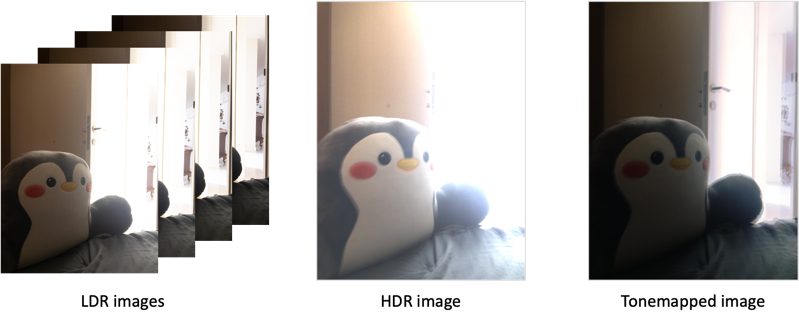

function [hdr_tone] = tonemapping_rgb(hdr, K, B)
    N = size(hdr,1)*size(hdr,2);
    eps = 0.00001;
    for c=1:3
        avg_lum = exp(1/N*sum(log(hdr(:,:,c)+eps), "all"));
        hdr_normed = hdr(:,:,c)/avg_lum*K;
        white = B*max(hdr_normed, [], 'all');
        hdr_tone(:,:,c) = hdr_normed./(1+hdr_normed).*(1+(hdr_normed/(white^2)));
    end
    
end

function [hdr_tone] = tonemapping_lumi(hdr, K, B)
    XYZ = rgb2xyz(hdr);
    X = XYZ(:,:,1);
    Y = XYZ(:,:,2);
    Z = XYZ(:,:,3);
    x = X./(X+Y+Z);
    y = Y./(X+Y+Z);

    N = size(hdr,1)*size(hdr,2);
    eps = 0.00001;
    
    avg_lum = exp(1/N*sum(log(Y+eps), "all"));
    hdr_normed = Y/avg_lum*K;
    white = B*max(hdr_normed, [], 'all');
    Y = hdr_normed./(1+hdr_normed).*(1+hdr_normed/(white^2));
    
    [X,Y,Z] = xyY_to_XYZ(x,y,Y);
    hdr_tone = xyz2rgb(cat(3,X,Y,Z));
end 

